# `Armadura Simples`

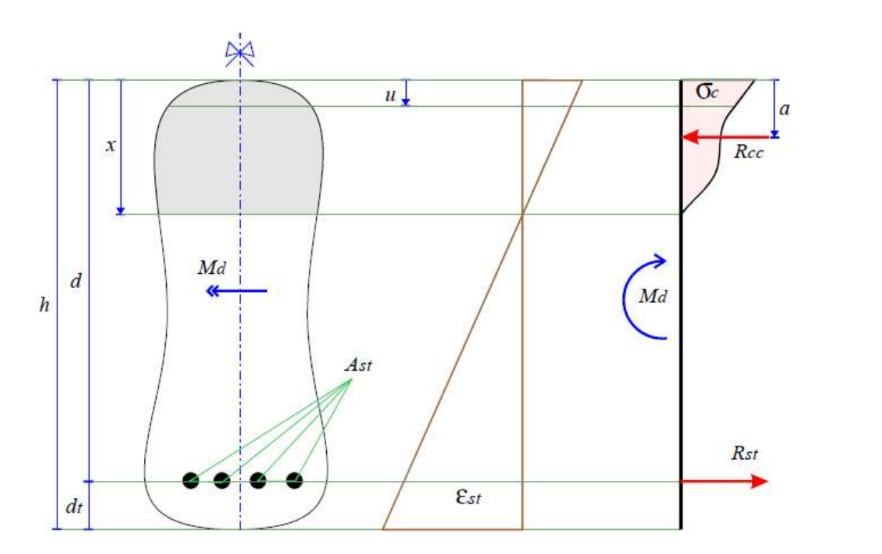

## `Problema de Verificação`

`Nesse caso o Momento último e a linha neutra são Icógnitas do seguinte sistema:`

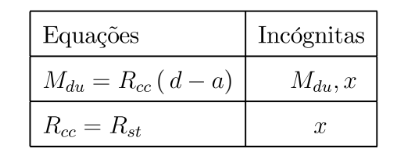

Realizaremos o processo análogo ao anterior, ou seja, utilizar um método numérico para obter a raíz da função:

Definindo ambas as funções por partes, cabe ressaltar que por ser monotonicamente crescente em relação a x, garante que essa equação será única.

### Definindo os Dados

clear;
C = 20;
fck = 20000000;

%Função ec2(fck,C) %corrigir nova norma
Sigma_cd = 0.85*fck/1.4;
e_c2 = ec2(fck,C);

%Função n(fck,C)
n_concreto = n(fck,C);

%Função ecu(fck,C)
e_cu = ecu(fck,C);

%Função kxlim(C)
kx_lim = kxlim(C);

%Constantes
f_yk = 500;
f_yd = f_yk /1.15 *10^6;
e_yd = 1000*f_yd/(210*10^9); %depende do material, esse é o aço C50, 500 MPa, troque os valores

### Definindo as dimensões da viga e da armadura

% Área (m)
b = 0.20;
h = 0.50;

%Momento Fletor para Verificar (lembrando se caso Mk, multiplicar por 1,4)
Mf = 84000;

%Area da Seção
diameter_t = 32*10^-3;
A_st = 4*pi* (diameter_t/2) ^2;


% Altura da Armadura (m)
dt = 0.02 + diameter_t/2;
d = h-dt; 

### Definindo os Domínios e os Limites

%Definição dos Domínios
%por Simplicidade adotaremos por exemplo,xlim 2a-2b como xlim2b, ou seja, sempre o
%último domínio define a variável

xlim2b = d*e_c2/(e_c2 + 10);
xlim3 = d*e_cu/(e_cu + 10);
xlim = d*kx_lim;

### Definindo as funções 

Definição da função 

%Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3)

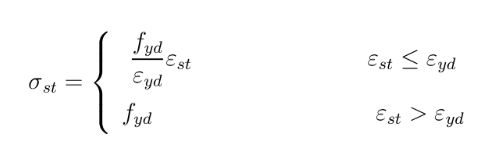

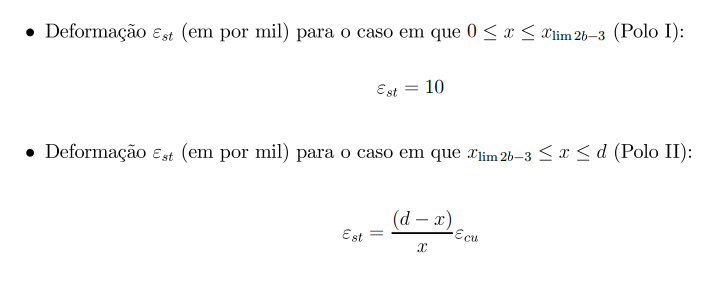

Rst = @(x) sigma_st(f_yd,e_yd,x,xlim3,xlim,e_cu,d)*A_st;   

f =@(x) Rcc(Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3) - Rst(x);

`Aplicando o Método da Bissecção`

% Definir a tolerância e o número máximo de iterações
tolerance = 1e-12;
max_iter = 1000;
xi = 0;
xf = d;

% Implementar o método da bissecção
for iter = 1:max_iter
    % Calcular o ponto médio
    c = (xi + xf) / 2;
    
    % Avaliar f(a), f(b) e f(c)
    fa = f(xi);
    fb = f(xf);
    fc = f(c);
    
    % Verificar a condição de parada
    if abs(fc) < tolerance || (xf - xi) / 2 < tolerance
        linha_neutra = c;
     
        fprintf('x = %.6f cm, kx = %.6f', linha_neutra, linha_neutra/d);
        
        break;
    end
    
    % Atualizar os valores de a e b
    if fa * fc < 0
        xf = c; % A raiz está entre a e c
    else
        xi = c; % A raiz está entre c e b
    end
end

x = 0.279759 cm, kx = 0.602930


if iter == max_iter
    fprintf('O método atingiu o número máximo de iterações\n');
end

### Segunda Parte do Exercício

Consiste na Resolução da primeira Equação

`Analogamente, `

## 

## 

## 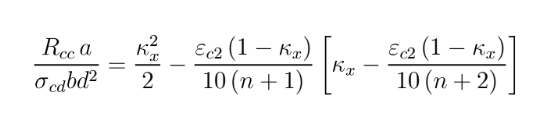

## 

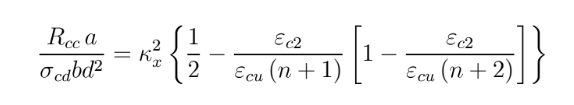

`Solução da Equação`

Md = @(x) d * Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3) - Rcca (Sigma_cd , b , d , e_c2 , e_cu , n_concreto , x , xlim2b , xlim3 , xlim );
 Md(linha_neutra)/1400

ans = 351.7410

### Verificação dos Dados

if Md(linha_neutra) < Mf
    fprintf('O Momento é menor que a máxima solicitação suportada pela seção, logo a seção está segura\n');
else
    if(linha_neutra/d < kx_lim)
       fprintf('O momento é maior ou igual a máxima solicitação suportada, mas a linha neutra está acima do que indica do k_lim, falha indicada\n'); 
    else
       fprintf('O momento é maior ou igual a máxima solicitação suportada e a linha neutra está abaixo do que indica do k_lim, atingindo o limite de ductilidade (ruína frágil) \n');
    end
end

O momento é maior ou igual a máxima solicitação suportada e a linha neutra está abaixo do que indica do k_lim, atingindo o limite de ductilidade (ruína frágil) 


# `Armadura Dupla`

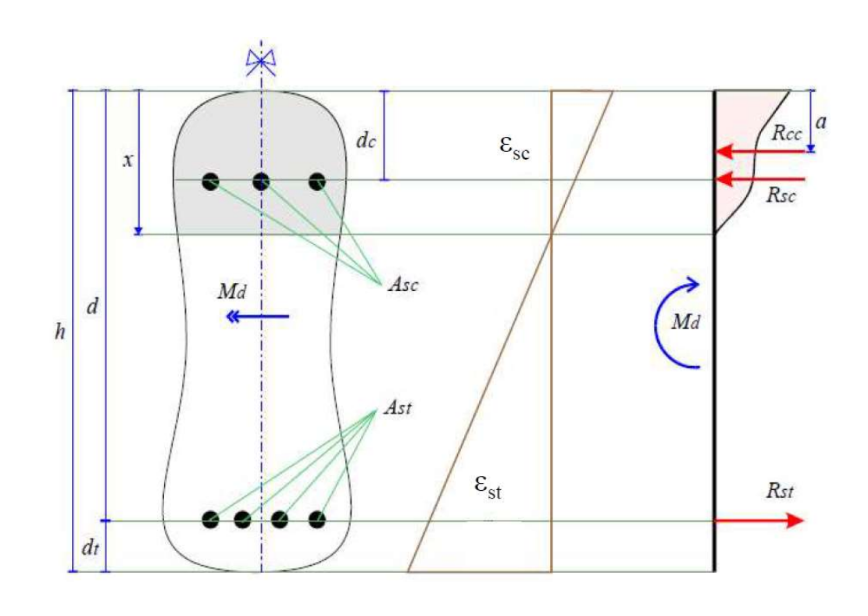

A equação se particulariza:

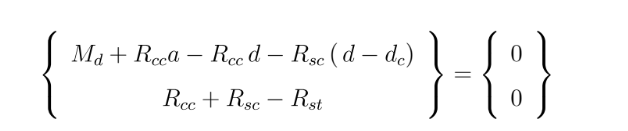

No entanto nesse caso as icógnitas ainda são apenas Mdu e x, o que indica que basta adicionar Rsc à segunda equação e realizar o mesmo procedimento

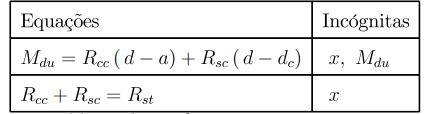

Definição dos Parâmetros

diameter_s = 10*10^-3;
Asc = 2*pi*(diameter_s/2)^2;
dc = 0.04;

Rsc = @(x) sigma_sc(f_yd,e_yd,x,xlim3,xlim,e_cu,d,dc)* Asc;

%definindo a função para encontrar raíz
f =@(x) Rcc(Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3) - Rst(x) + Rsc(x) ;

`Aplicando o Método da Bissecção`

% Definir a tolerância e o número máximo de iterações
tolerance = 1e-6;
max_iter = 1000;
xi = 0;
xf = xlim;

% Implementar o método da bissecção
for iter = 1:max_iter
    % Calcular o ponto médio
    c = (xi + xf) / 2;
    
    % Avaliar f(a), f(b) e f(c)
    fa = f(xi);
    fb = f(xf);
    fc = f(c);
    
    % Verificar a condição de parada
    if abs(fc) < tolerance || (xf - xi) / 2 < tolerance
        linha_neutra = c;
     
        fprintf('x = %.6f cm', linha_neutra);
        
        break;
    end
    
    % Atualizar os valores de a e b
    if fa * fc < 0
        xf = c; % A raiz está entre a e c
    else
        xi = c; % A raiz está entre c e b
    end
end

x = 0.162399 cm

Aplicando na segunda Equação

Md = @(x) d * Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3) - Rcca (Sigma_cd , b , d , e_c2 , e_cu , n_concreto , x , xlim2b , xlim3 , xlim ) + Rsc(x)*(d-dc);
fprintf('%.6f kN.m', Md(linha_neutra)/1000); 

352.006786 kN.m